# Numerical Methods for Optimization and Control Theory

## Assignment 1 - Daniel Kuknyo

Tasks assigned: 2, 5, 7, 13

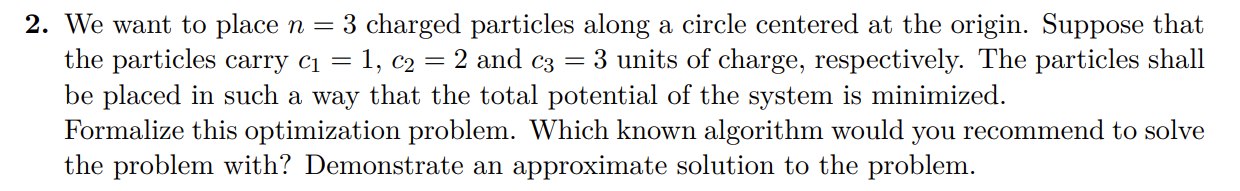

## Problem:

The system is in a state of equilibrium when the potential function is minimized. The electrostatic interaction energy between each pair of equally charged particles is given by Coulomb's law:


$$U_{i,j} \left(N\right)=k_e \frac{e_i \;e_j }{r_{i,j} }$$


Where $k_e$ is Coulomb's constant. In the numerator $e_i$ is the charge of particle $i$ and $e_j$ is the charge of particle $j$. The denominator $r_{i,j} =|r_i -r_j |$ is the distance between each pair of particles $i,j$ located at points $r_i$ and $r_j$. $N$ is the number of particles. We can assume that the circle is unit as there was no specification for a radius. 

## Formalization:

- 
$$N=3$$


- 
$$k_e =8\ldotp 9875517923\times {10}^9$$


- 
$$r_{i,j} =\sqrt{{\left(i_1 -j_1 \right)}^2 +{\left(i_2 -j_2 \right)}^2 }$$


#### Objective: 

The potential between two particles $i,j$:

- 
$$U_{i,j} =$$

$$k_e \frac{e_i \;e_j }{r_{i,j} }$$


The total potential of the system is the sum of the pairwise potentials:

- 
$$U\left(p_1 ,p_2 ,\ldotp \ldotp \ldotp ,p_N \right)=\;\sum_{i<j}^N \;k_e \frac{e_i \;e_j }{r_{i,j} }$$


The objective function:

- 
$$\underset{p_1 ,p_2 ,\ldotp \ldotp \ldotp ,p_N \in \mathit{\mathbf{R}}}{\min \;} U\left(p_1 ,p_2 ,\ldotp \ldotp \ldotp ,p_N \right)$$


#### Constraints:

The particles are on the unit circle: $R:=1$

- 
$$x_1^2 +y_1^2 -1=0$$


- 
$$\vdots$$


- 
$$x_N^2 +y_N^2 -1=0$$


### Simplification:

We can use polar coordinates with variables $r$ for the radius and $\varphi$ for the angle between the radius and the polar axis. This way, instead oh having to find two coordinates for each charged particle we only have to find the angle, because $r=1$ is a constant for the unit circle. Coulomb's constant can also be left out of the equation as it will not change the minimum location.

#### Coordinates:

- 
$$x=r\;\cos \left(\varphi \right)$$


- 
$$y=r\;\sin \left(\varphi \right)$$


- 
$$\left(x,y\right)=\left(r\;\cos \left(\varphi \right),\;r\;\sin \left(\varphi \right)\right)$$


#### Distance function:

- 
$$r_{i,j} =\sqrt{r_1^2 +r_2^2 -2\;r_1 r_2 \;\cos \left(\varphi_1 -\varphi_2 \right)}$$


- $r_{i,j} =$$\sqrt{2-2\;\cos \left(\varphi_1 -\varphi_2 \right)}$ in case of the unit circle

#### Objective:

Now we have $N$ variables instead of $\frac{N}{2}$.

- 
$$\min_{y\;\in \;{\mathit{\mathbf{R}}}^n } \;U\left(\varphi_1 ,\varphi_2 ,\ldotp \ldotp \ldotp ,\varphi_N \right)$$


#### Constraints:

For every $i=1,2,\ldotp \ldotp \ldotp ,N$

- 
$$\varphi_i \ge 0$$


- 
$$\varphi_i <2\pi {\;\textrm{or}\;\varphi }_i <360$$
 

- 
$$r_i =1$$


We can discard all inequality constraints due to periodicity. The $r_i =1\;$equality constraint will be discarded automatically as we don't store the radius of the coordinates, rather just always assume that it's $1$, e.g. in the distance function. Finally we end up with an unconstrained global optimization problem with $N$ variables for $N$ particles.

### Which algorithm can be used to solve this problem?

I would recommend solving this problem using the Gradient Descent algorithm. The objective function is differentiable, and we can compute the gradient using traditional methods. This makes this a good candidate for Gradient Descent. 

### Initialize particles

x0 = [randi([0 359],1,1); % Charge, random angle initialization
      randi([0 359],1,1); 
      randi([0 359],1,1)]

x0 =    221
   170
   126


total_potential(x0)

ans = 24.7315

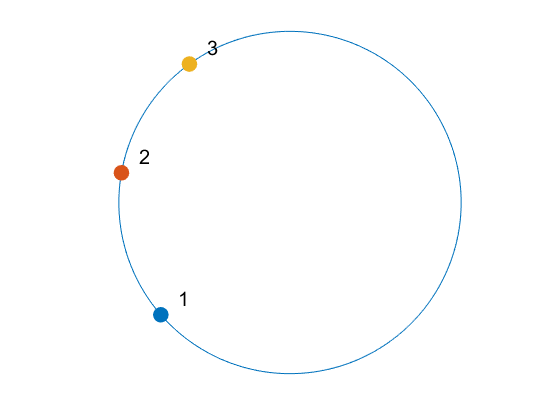

plot_thomson(x0)

### Demonstrating an approximate solution using Gradient Descent

iter = 10000; 
x = descent_potential(@total_potential, @gradient_potential, 0.01, x0, iter)

x =   185.4624
  277.0482
   54.4894


total_potential(x)

ans = 12.5263

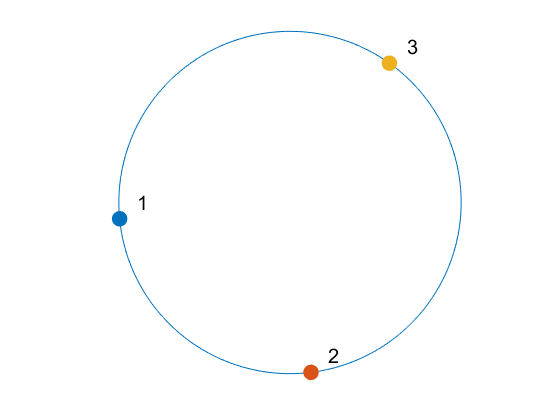

plot_thomson(x)

### Functions

function dist = polar_distance(phi1, phi2) % The distance between two polar coordinates
    rad_deg = 0.01745329; % Convert to radians
    phi1_rad = phi1 * rad_deg;
    phi2_rad = phi2 * rad_deg;
    dist = sqrt(2 - 2 * cos(phi1_rad - phi2_rad));
end

function x = polar2rect(r, p) % Polar --> rectangular coordinate conversion
    rad_deg = 0.01745329; % Convert to radians
    p_rad = p * rad_deg;
    x = [r * cos(p_rad) r * sin(p_rad)];
end

function U = total_potential(x) % Total potential of the system
    c = [1;2;3];
    U = 0;
    n = size(x, 1);
    for i=1:n
        for j=1:n
            if(j ~= i)
                U = U + (c(i) * c(j)) / polar_distance(x(i), x(j));
            end
        end
    end
end

function dU = gradient_potential(x) % Gradient of the potential function
    rad_deg = 0.01745329;    
    c = [1;2;3];
    dU = [0; 0; 0];
    n = size(x, 1);
    for i=1:n
        for j=1:n
            if(j ~= i)
                d = polar_distance(x(i), x(j));
                e = c(i) * c(j);
                ang = (x(i) - x(j)) * rad_deg;
                %dU(i) = dU(i) - e / d^e;
                dU(i) = dU(i) + ((e * sin(ang)) / (2-2*cos(ang))^(3/2)); 
            end
        end
    end
end

function x = descent_potential(f, df, alpha, x0, iter) % GD on the potential function
    x = x0;
    best_x = x;
    best_tp = 1000;
    for k = 1:iter
        p = -df(x);
        x = x + alpha*p;
        x = mod(x, 360);
        tp = total_potential(x);
        if(tp < best_tp)
            best_tp = tp;
            best_x = x;
        end
    end
    x = best_x;
end

function plot_thomson(x) % Plot the Thomson problem on a unit circle
    x_rect = [polar2rect(1, x(1)); polar2rect(1, x(2)); polar2rect(1, x(3))];
    j = size(x_rect, 1);
    
    figure; hold on;
    c = [0 0]; % center
    r = 1; % radius
    n = 1000; % number of points
    
    t = linspace(0,2*pi,n); % running variable
    x = c(1) + r*sin(t);
    y = c(2) + r*cos(t);
    
    line(x,y) % draw circle
    
    for i=1:j % plot the points and numbers
        plot(x_rect(i,1), x_rect(i,2),'.','MarkerEdgeColor',"auto",'MarkerFaceColor', ...
            "auto",'MarkerSize',40);
        text(x_rect(i,1)+0.1, x_rect(i,2)+0.1, string(i), 'FontSize', 15);
    end

    axis equal
    axis off
    hold off;
end